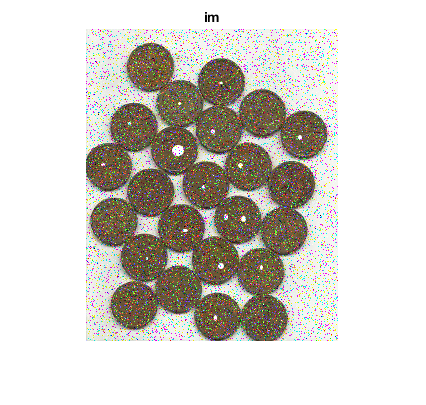

% T = graythresh(I) computes a global threshold T from grayscale
% image I, using Otsu's method [1]. Otsu's method chooses a threshold
% that minimizes the intraclass variance of the thresholded black and
% white pixels. The global threshold T can be used with imbinarize to
% convert a grayscale image to a binary image.

im = imread("D:\repos\Computer Vision\Lab 5\holes_corrupted_coins.png");
imP = Process(im);
imP2 = Process2(im);

imshow(im)
title("im");

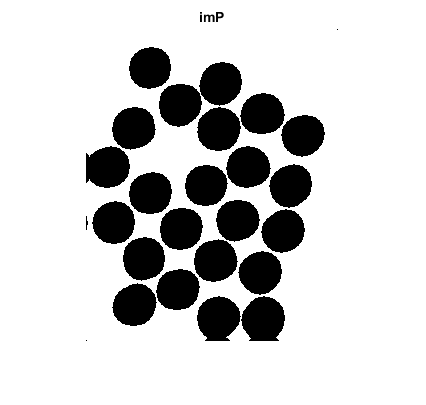

imshow(imP)
title("imP");

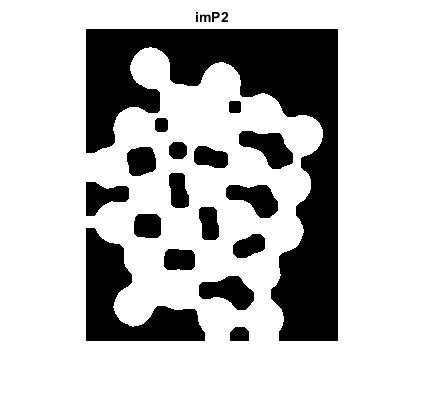

imshow(imP2)
title("imP2");

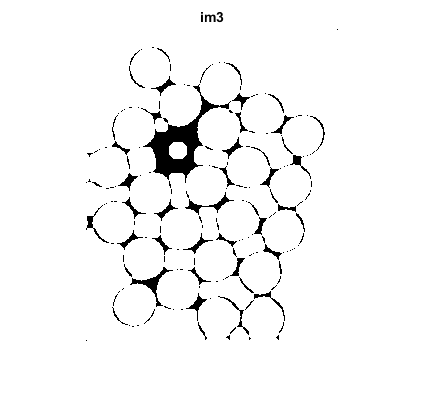

im3 = xor(imP2, imP);
imshow(im3)
title("im3");

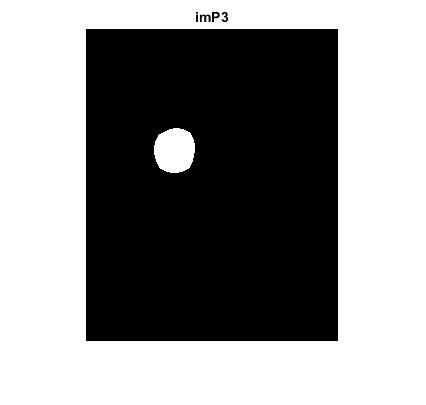

imP3 = Process3(im3);
imshow(imP3)
title("imP3");

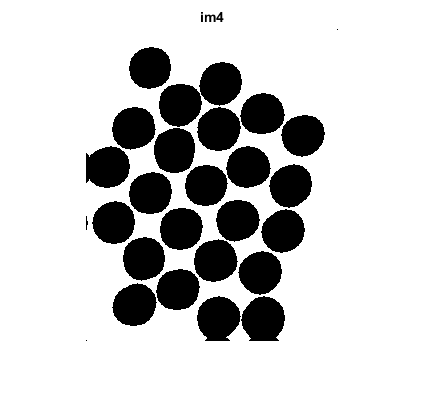

im4 = ~imP3 & imP;
imshow(im4)
title("im4");

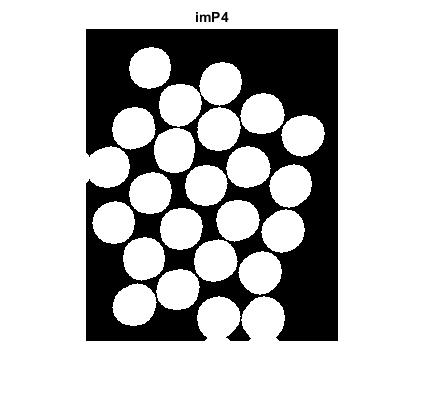

imP4 = Process4(im4);
imshow(imP4)
title("imP4")

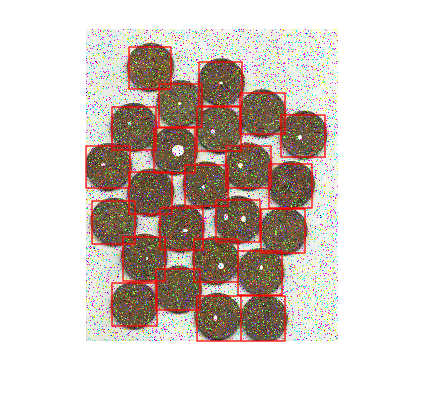

ans = 24×23 table
    Area        Centroid                  BoundingBox                        SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage      ConvexArea         Image           FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList         PixelList       Perimeter    PerimeterOld
    ____    ________________    ________________________________    ______________________________    _____

24 objects detected



imshow(im)
DrawRois(imP4,'r');

Largest coins has an area of 1541


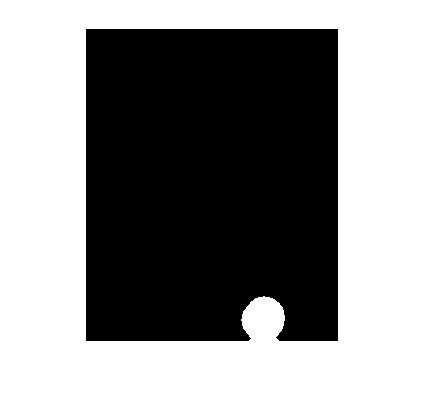


largestCC = GetLargestCC(imP4);

Smallest coins has an area of 1402


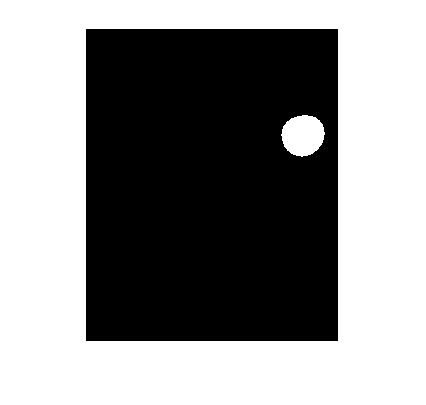

smallestCC = GetSmallestCC(imP4);


imshow(im)
DrawRois(largestCC, 'r');

ans = 1×23 table
    Area        Centroid                  BoundingBox                        SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage      ConvexArea         Image           FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList         PixelList       Perimeter    PerimeterOld
    ____    ________________    ________________________________    ______________________________    ______

1 objects detected


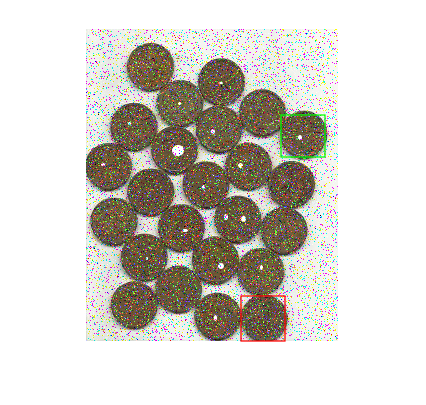

ans = 1×23 table
    Area        Centroid                  BoundingBox                        SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation     ConvexHull        ConvexImage      ConvexArea         Image           FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList         PixelList       Perimeter    PerimeterOld
    ____    ________________    ________________________________    ______________________________    ______

1 objects detected


DrawRois(smallestCC, 'g');


GetDistance(largestCC, smallestCC)

Error: Functions cannot be indexed using {} or . indexing.

Error in EX1L6>GetDistance (line 187)
    cc1y = regionprops("table", CC1,"All").Centroid(1);


PlotLine(im, largestCC, smallestCC, 'm')
DrawRois(largestCC, 'r');
DrawRois(smallestCC, 'g');

function imP = Process(im)
    % Convert to greyscale
    imP = rgb2gray(im);
    imP = imgaussfilt(imP, 0.47);
    imP = medfilt2(imP);

    % https://uk.mathworks.com/help/images/noise-removal.html
    imP = filter2(fspecial('average',5),imP)/255;
    
    imP = imfill(imP, 'holes');
    % Morphological ops
    se = strel('line',5,200);
    imP = imerode(imP, se);
    
    % Otsu's Graythresh
    level = graythresh(imP);
    imP = imbinarize(imP,level);
    
    % Morphological ops
    se = strel('diamond', 5);
    imP = imdilate(imP, se);
    
    se = strel('sphere',17);
    imP = imclose(imP, se);
end

function imP = Process2(im)
    
    % Convert to greyscale
    imP = rgb2gray(im);
    
    imP = filter2(fspecial('average',9),imP)/255;
    imP = medfilt2(imP);
    
    level = graythresh(imP);
    imP = ~imbinarize(imP,level);
    
    se = strel('disk', 2);
    imP = imerode(imP, se);
    se = strel('disk', 3);
    imP = imclose(imP, se);
    se = strel('disk', 3);
    imP = imerode(imP, se);
    
% % % % % % %     
    
%     insideMasked = rgb2gray(im);
%     insideMasked(~imP) = 0;
%     
%     imshow(insideMasked)
%     
%     outsideMasked = rgb2gray(im);
%     outsideMasked (imP) = 0;
%     
%     imP = outsideMasked;

%     imP = medfilt2(imP);
%     imP = filter2(fspecial('average',5),imP)/255;
    
end

function imP = Process3(im)
    imP = im;
    imP = filter2(fspecial('average',3),imP);
    se = strel('sphere', 1);
    imP = imerode(~imP, se);
    imP = medfilt2(imP);
    imP = imfill(imP, 'holes');
    se = strel('sphere', 16);
    imP = imerode(imP, se);
    se = strel('sphere', 15);
    imP = imdilate(imP, se);
    se = strel('disk', 2);
    imP = imerode(imP, se);
    se = strel('sphere', 10);
    imP = imdilate(imP, se);
    se = strel('disk', 5);
    imP = imerode(imP, se);
end

function imP = Process4(im)
    imP = bwareaopen(~im, 50);
end

function DrawRois(imP, c)
    CC = bwconncomp(imP);
%     L = labelmatrix(CC);
%     RGB = label2rgb(L,'cool','k','shuffle'); 
%     imshow(RGB)
    regionprops("table",CC,"all")
    
    % DRAW BOUNDING BOXES AND GET BLOB COUNT
    disp(CC.NumObjects + " objects detected")
    info = regionprops(CC,'Boundingbox') ;
%     imshow(original) % to overlay bounding boxes
    % hold on
    for k = 1 : length(info)
         BB = info(k).BoundingBox;
         rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',1) ;
%          rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',1,"Curvature",[1,1]) ;
    end
end

function largest = GetLargestCC(imP)
    CC = bwconncomp(imP);
    largest = 0;
    largestIndex = 0;
    props = regionprops("table", imP, "All");
    
    for i=1:size(props.Area)
        if props.Area(i) > largest
            largest = props.Area(i);
            largestIndex = i;
        end
    end
    
    disp("Largest coins has an area of " + props.Area(largestIndex))
    largest = bwareafilt(imP, [largest largest]);
    imshow(largest)

end

function smallest = GetSmallestCC(imP)
    CC = bwconncomp(imP);
    smallest = 0;
    smallestIndex = 0;
    props = regionprops("table", imP, "All");
    
    for i=1:size(props.Area)
        if props.Area(i) < smallest || props.Area(i) > 0
            smallest = props.Area(i);
            smallestIndex = i;
        end
    end

    disp("Smallest coins has an area of " + props.Area(smallestIndex))
    smallest = bwareafilt(imP, [smallest smallest]);
    imshow(smallest)

end

function distance = GetDistance(CC1, CC2)
    cc1y = regionprops("table", CC1,"All").Centroid(1);
    cc1x = regionprops("table", CC1,"All").Centroid(2);
    cc2y = regionprops("table", CC2,"All").Centroid(1);
    cc2x = regionprops("table", CC2,"All").Centroid(2);
%     [cc2y, cc2x] = regionprops("table", CC2,"All").Centroid;
    X = [cc1y,cc2y;cc1x,cc2x];
    distance = pdist(X,'euclidean');
end

function PlotLine(im,CC1, CC2,c)
    imshow(im)
    cc1y = regionprops("table", CC1,"All").Centroid(1);
    cc1x = regionprops("table", CC1,"All").Centroid(2);
    cc2y = regionprops("table", CC2,"All").Centroid(1);
    cc2x = regionprops("table", CC2,"All").Centroid(2);
%     [cc2y, cc2x] = regionprops("table", CC2,"All").Centroid;
    line([cc1y, cc2y],[cc1x, cc2x],'Color' , c, 'LineWidth', 2)
end
